# risolve - Analisi di robustezza, accuratezza e prestazioni 

In questo documento sono mostrati i test relativi all'algoritmo per la risoluzione dei sistemi lineari implementato. L'accuratezza è valutata mediante il calcolo dell'errore relativo creando sistemi **adHoc** di cui si conosce la soluzione. Mentre per misurare le prestazioni dell'algoritmo è stato misurato il tempo richiesto per ottenere la soluzione con `risolve` e sono stati confrontati con i tempi della funzione `mldivide` offerta dal Matlab. 

# Test di accuratezza

Per testare l'accuratezza dell'algortimo realizzato, si è utilizzata come metrica di valutazione l'errore relativo calcolato come norma della differenza tra la soluzione trovata l'algoritmo ( xRisolve ) e quella reale ( x ) normalizzati rispetto la norma della soluzione reale .


$$\frac{\left\|\mathrm{xRisolve}-x\right\|}{\left\|x\right\|}$$
  

**Nota :**  Per soluzione reale si intende la soluzione nota a priori del sistema. Infatti , anche se calcolassimo  la soluzione di un sistema, `A*x=b,` con `mldivide` ( funzione del MatLab per la soluzione di sistemi lineari ) avremmo una soluzione affetta da errore e quindi  non potremmo mai calcolore la soluzione reale di un sistema lineare. Quindi, se non realizzassimo sistemi **adHoc**, la nostra metrica non sarebbe valida in quanto la soluzione reale sarebbe comunque affetta da errore, che non è noto a priori in quanto è dovuto dagli elementi che compongono la matrice `A`. 

Per effetturare i test si sceglie prima la matrice `A `( Matrice dei coefficienti ), il vettore `x `( Soluzione reale ) e si calcola il vettore `b` ( Vettore dei coefficienti ) come `A*x'` . Questi parametri devono essere passati in input alla funzione `risolveAccuracy`  che  calcola l'errore relativo della soluzione ottenuta con `risolve` , l'indice di condizionamento della matrice `A e `se la matrice è piena calcola il residuo tra la soluzione reale e  quella ottenuta con `risolve`. Tale funzione ritorna una struttura coi i seguenti campi : `cond`, `rcond`, `errore` e `residuo`. Si rimanda il lettore alla documentazione delle funzione per maggiori informazioni .

**Esempi**

A = triu(rand(100) *6 ); % matrice diagonale superiore bencondizionata
x = ones(100,1);
b = A*x;
accuracy = risolveAccuracy(A,x,b,'sup')

accuracy = struct with fields:
       cond: 2.6976e+17
      rcond: 3.3900e-19
     errore: 9.9765e+11
    residuo: -1


A = tril( rand(100) ); % matrice diagonale inferiore bencondizionata
x = ones(100,1);
b = A*x;
accuracy = risolveAccuracy(A,x,b,'inf')

accuracy = struct with fields:
       cond: 4.0732e+17
      rcond: 5.7706e-19
     errore: 5.0088e+13
    residuo: -1


A = hilb(13)  ; % matrice malcondizionata
x = ones(13,1);
b = A*x;
accuracy = risolveAccuracy(A,x,b,'full')

accuracy = struct with fields:
       cond: 4.7864e+17
      rcond: 1.1721e-18
     errore: 1.6330e+08
    residuo: 4.3962e-09


format long;
opt.full=true;
x = risolve(A,b,opt);
x(1:10)

ans =    1.000000068924764
   0.999989223993082
   1.000413538110348
   0.993147494692574
   1.061246208216431
   0.669261244460048
   2.149074131449130
  -1.654171189792307
   5.118548079749083
  -3.243049939320393


Si osservi che nell'ultimo test, l'erorre relativo è molto grando quindi la soluzione non è accurata e si nota subito dalla presenza di soluzioni negative che non dovrebbero esserci ! 

Per completezza si informa il lettore che è presente una funzione, `risolveAccuracyMesurement` , che realizza un **file excel **contente i risultati di `risolveAccuracy, `eseguito sia su matrici tringolari che piene, di dimensioni che variano tra un estremo inferiore ( `inf` ) e uno superiore ( `sup` ). Gli elementi delle matrici sono generati in maniera casuale .

risolveAccuracyMesurement(5,40);


num =

     []



La funzione genera il file `accuracyMesurement.xlsx` che contiene tre fogli,  ognuno dei quali flio contiene i dati relativi alle misurazioni eseguite su un particolare tipo della matrice `A.`

# Prestazioni

Sono stati valutati i tempi di esecuzione dell'algoritmo implementato confrontandoli con  la soluzione offerta da Matlab  ( `mldivide, \ `).  La funzione `risolvePerformance,` allegata alla documentazione, effettua una misurazione dei tempi di `risolve` e di `mldivide `eseguiti su delle matrici generate casulamente con la dimensione che varia tra l'estremo inferiore ( inf ) e l'estremo superiore ( sup ). Al termine dell'esecuzione genera un grafico che mostra l'andamento dei tempi di esecuzione richiesti dagli algoritmi citati precedentemente per ottenere la soluzione dei sistemi, indipendentemente dall'indice di condizionamento della matrice `A`. Di seguito viene riportata l'esecuzione della misurazione relativa al caso in cui `A `sia una matrice piena. Infatti in questo caso il nostro algoritmo ha una complessità computazionale **cubica** perché prevede prima l'esecuzione dell'algoritmo di  **gauss **che trasforma la matrice `A in `una triangolare in modo tale da poter applicare l'algoritmo di `back_substitution.`

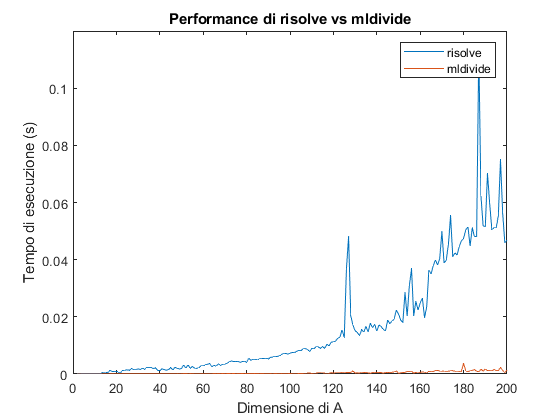

risolvePerformance(2,200,'full')

Si osservi che la soluzione del Matlab è molto più efficiente perché si avvantaggia di simmetrie presenti nel problema, utilizzando risolutori specifici ( si veda la documentazione di `mldivide `per maggiori informazioni ) [1].

# Test di robustezza

Per la progettazione dei casi di test è stato utilizzato il metodo di Category-partition testing [1], ampiamente diffuso nell'ambito dell'Ingegneria del Software per il testing funzionale. In particolare, le categorie sono state scelte in base ai parametri (di ingresso ) modificabili dall'utente e in base agli elementi della matrice `A.` I valori sono stati scelti in base alle condizioni di errore/warning in modo tale da verificare che in caso di errori in input i warning e gli errori vengono correttamente scatenati .

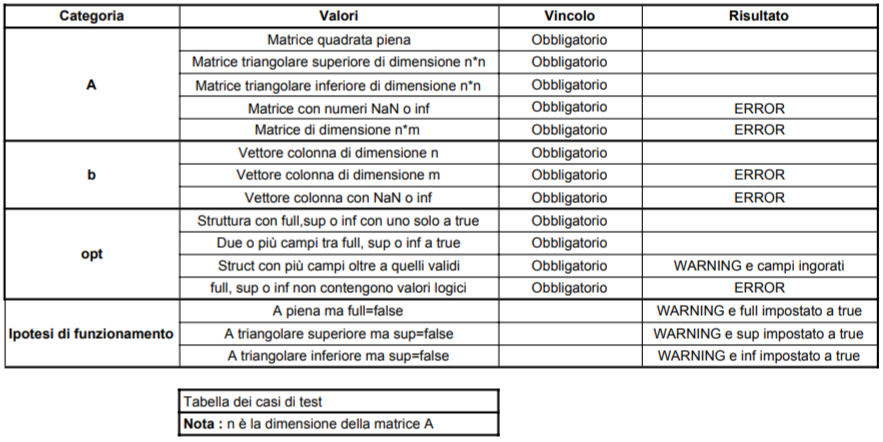

Il numero di casi di test è: 5 + 3 + 4 + 3 = 15.

Per l'implementazione dei casi di test è stato utilizzato il framework di MatLab per il testing di unità [2]*; *questa scelta ha permesso di automatizzare completamente l'esecuzione dei test: infatti, è possibile lanciare la simulazione con l'istruzione

results = runtests('testSuite.m')

Running testSuite
.......... .....
Done testSuite
__________



results =   1×15 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   15 Passed, 0 Failed, 0 Incomplete.
   0.20761 seconds testing time.


Il sistema esegue in automatico i test, riportando in `results `un sommario di quanti hanno avuto successo e dettagliando gli errori in quelli che eventualmente sono falliti. 

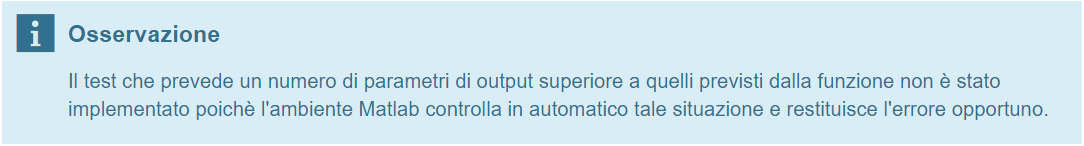

***Nota:**** Per semplicità non sono stati implementati i test relativi a dati di input che contenessero valori invalidi *`NaN/Inf`*.*

Di seguito viene descritta l'implementazione di alcuni casi di test a titolo esemplificativo.

## Caso di test 1

Configurazione dei parametri :

- `A:`                  triangolare superiore

- `b:         `valido

- `opt.full `=   true

function testFunctionCase1(testCase)
    A = triu(rand(10));
    x = ones(10,1);
    b = A*x;
    opt.full=true;
    
    testCase.verifyWarning(@()risolve(A,b,opt),'risolve:optWarning1')
end

La funzione `risolve `esegue l'algoritmo `backSubstitution` ma restituisce un warning a causa del fatto che la struttura `opt `passata non ha il campo `sup `settato a `true.`

## Caso di test 6

Configurazione dei parametri : 

- `A :`       triangolare inferiore

- `b : `     non valido

- opt :      non valido 

function testFunctionCase6(testCase)
    A = tril(rand(10));
    b = rand(11,1);
    opt.full=true;
    opt.sup=true;
    
    testCase.verifyError(@()risolve(A,b,opt),'risolve:bInvalidDimension')
end

Anche se opt presenta più campi impostati a true, non viene sollevato l'errore dovuto al malcondizionamento di opt, perchè viene prima sollevato l'eccezione relativa al fatto che la dimension di b non sia coerente con quella di `A`. Infatti la priorità è controllare prima se è `A` è valida, poi il vettore `b` e infine si controlla `opt`.

## Caso di test 8

La configurazione dei parametri è:

- `A:`                  triangolare superiore, singolare

- `b:`                   valido

- `opt.sup    `=true

function testFunctionCase8(testCase)
    A = triu(rand(10));
    A(1,1)=0;
    x = ones(10,1);
    b = A*x;
    opt.sup=true;
    
    testCase.verifyError(@()risolve(A,b,opt),'risolve:ASingular')
end

In questo caso, l'algoritmo verifica che la matrice `A` in input è singolare e restituisce errore .

## Caso di test 14

La configurazione dei parametri è:

- `A:`      sparsa

- `b:`      indifferente

- opt:    indifferente

function testFunctionCase14(testCase)
    A = sprand(10,10,0.01);
    x= ones(10,1);
    b = A*x;
    opt.full= true;
    
    testCase.verifyError(@()risolve(A,b,opt),'risolve:ANotMatrix')
end

La condizione di errore restituita è dovuta al fatto che `A è` una matrice sparsa e questo programma non prevede la risoluzione di sistemi espressi con matrice dei coefficienti sparse .

## Riferimenti

[1] *Robert D. Cameron, 2013, *[http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html](http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html)

[2] Matlab Documentation, [https://it.mathworks.com/help/matlab/function-based-unit-tests.html](https://it.mathworks.com/help/matlab/function-based-unit-tests.html)

## Autore

Gabriele Previtera